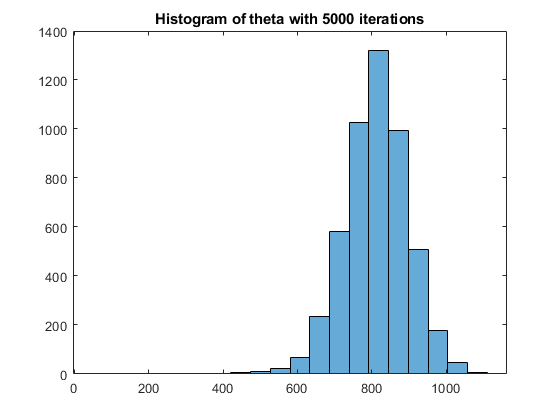

clear;
x = [91,504,557,609,693,727,764,803,857,929,970,1043,1089,1195,1384,1713];
n = length(x);
a = 3;
b = 3;
tau_sq = 100000;
theta_0 = 5;
T = 5000;
sigma_sq = 1/gamrnd(a,1/b);
theta = normrnd(theta_0,sqrt(tau_sq));
sigma_sq_a = (n/2) + a;

for i=2:T
    %update theta
    weight = sigma_sq(i-1)/(sigma_sq(i-1)+(n*tau_sq));
    theta_mu = (weight*theta_0) + ((1-weight)*mean(x));
    theta_var = weight*tau_sq;
    theta(i) = normrnd(theta_mu,sqrt(theta_var));
    
    %update sigma square
    sigma_sq_b = (sum((x-theta(i)).*(x-theta(i)))/2) + b;
    sigma_sq(i) = 1/gamrnd(sigma_sq_a,1/sigma_sq_b);
end

figure(1);
histogram(theta,20);
title(sprintf('Histogram of theta with %d iterations',T))

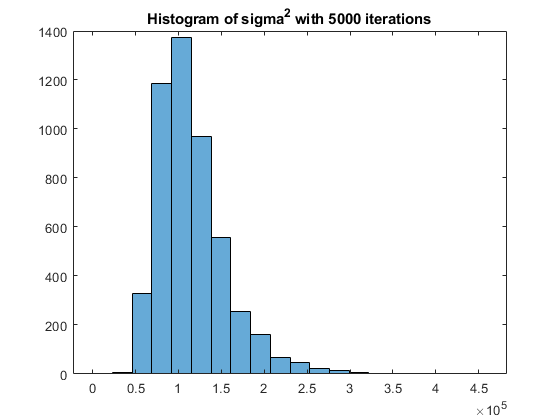

histogram(sigma_sq,20);
title(sprintf('Histogram of sigma^2 with %d iterations',T))